% Drift Experiments using 3D Point cloud Registration
% Start by making a drifted data set
clearvars;
close all;
clc;
settingsObj = settings;
settingsObj.matlab.editor.AllowFigureAnimation.TemporaryValue = 1;

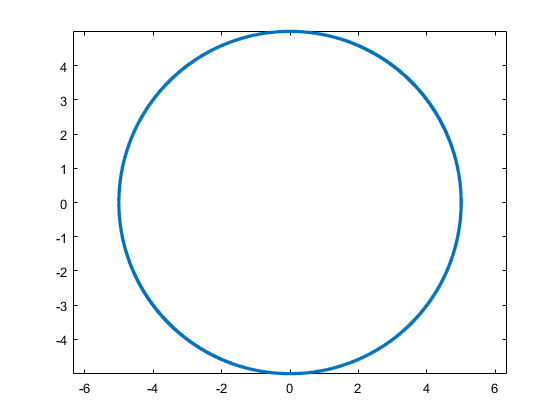

% Create an underlying structure
theta = 0:0.001:2*pi;
r = 5; % Create a circle of radisu r microns
truth_x = r*cos(theta);
truth_y = r*sin(theta);
plot(truth_x,truth_y,'.')
axis equal

truth_n = numel(truth_x);

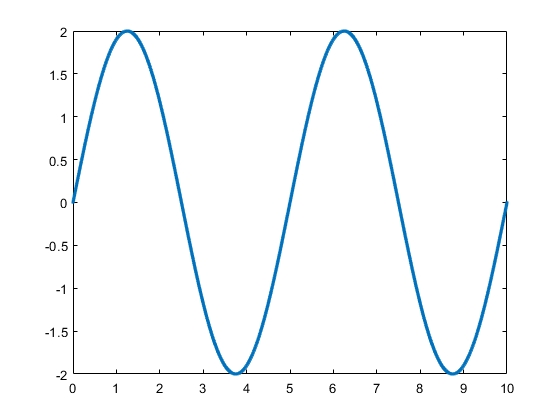

% Define the drift we expect
time = 1:10000;
v = 0.001; % Given other units this will be in microns per frame
drift_x = v*time;
drift_y = 2*sin(2*pi*time/5000);
drift_n = numel(drift_x);
plot(drift_x,drift_y,'.')

drift_x = drift_x(:);
drift_y = drift_y(:);

% Randomly sampling from the underlying structure with drift and noise
lps = 0.01; %localization precision
num_mols = 100000

num_mols = 100000

for i = 1:num_mols
    time_ind = randi(drift_n);
    loc_index = randi(truth_n);
    locs(i,:) = [truth_x(loc_index) + drift_x(time_ind) + randn(1)*lps,truth_y(loc_index)+ drift_y(time_ind) + randn(1)*lps, time(time_ind)];
    %     locs(i,:) = [truth_x(loc_index) ,truth_y(loc_index), time(time_ind)];
end

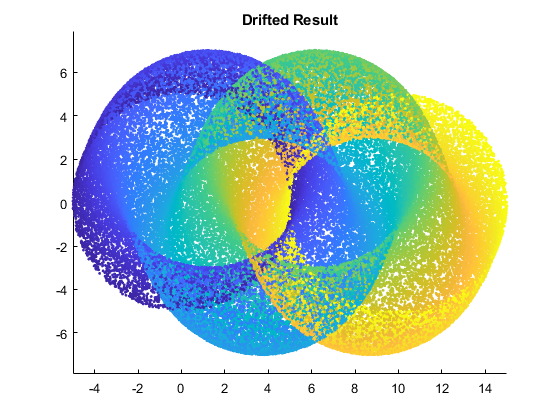

% Represent drifted dataset
scatter(locs(:,1),locs(:,2),5,locs(:,3),'filled')
title('Drifted Result')
axis equal

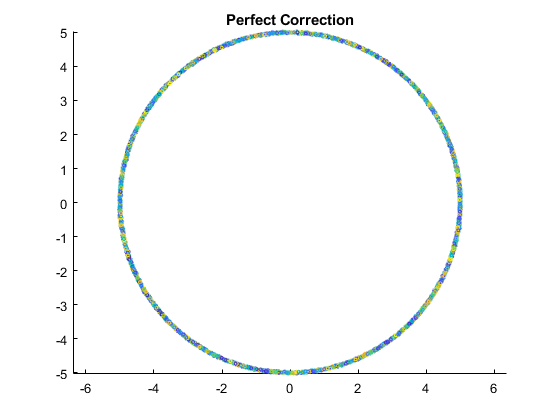

figure
scatter(locs(:,1) - drift_x(locs(:,3)),locs(:,2) - drift_y(locs(:,3)),5,locs(:,3))
title('Perfect Correction')
axis equal

% histogram(locs(:,3))

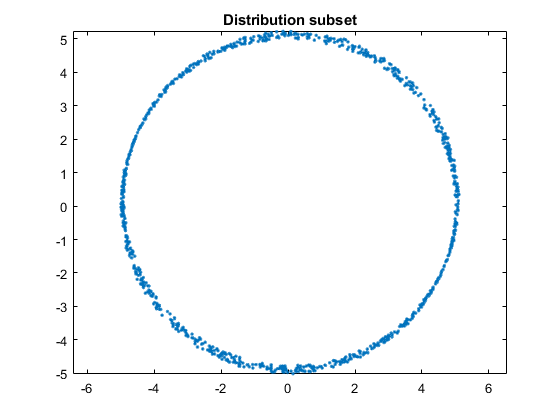

% Work on correcting this drift
% Drift at t = 0 is easy because it is the 'true' position
drift = [0 , 0];
% After this let's group by number of molecules
mol_chunks = 1000; % every mol_chunks consecutive molecules will be used to do the comparison calculation
sort_locs = sortrows(locs,3);
plot(sort_locs(1:mol_chunks,1),sort_locs(1:mol_chunks,2),'.')
axis equal
title('Distribution subset')

This section will be converted into the function nn_dirft_cost.m

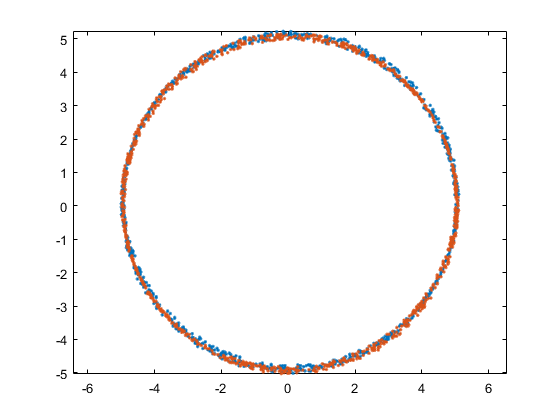

% Start be determining all nearest neighbor distances between subsets
clearvars frequency
bins = 100;
a = 100;
sub_locs_1 = sort_locs(1:mol_chunks,:);
sub_locs_2 = sort_locs(20*mol_chunks+1:21*mol_chunks,:);
sub_locs_2(:,2) = sub_locs_2(:,2)-1; 
sub_locs_2(:,1) = sub_locs_2(:,1)-2; 
plot(sub_locs_1(:,1),sub_locs_1(:,2),'.')
hold on
plot(sub_locs_2(:,1),sub_locs_2(:,2),'.')
hold off
axis equal

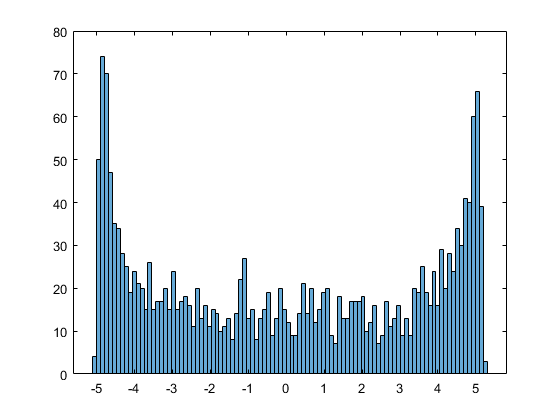

combo_sub = [sub_locs_1;sub_locs_2];
standard_x = combo_sub(:,1);
standard_y = combo_sub(:,2);
% standard_x = mod(a,a*(combo_sub(:,1) - min(combo_sub(:,1)))/(max(combo_sub(:,1))- min(combo_sub(:,1))));
% standard_y = mod(a,a*(combo_sub(:,2) - min(combo_sub(:,2)))/(max(combo_sub(:,2))- min(combo_sub(:,2))));
% standard_z = mod(a,a*(combo_sub(:,1) - min(combo_sub(:,1)))/(max(combo_sub(:,1))- min(combo_sub(:,1))));
[f_x] = histcounts(standard_x,bins);
[f_y] = histcounts(standard_y,bins);
histogram(standard_y,bins)

prob_x = f_x./sum(f_x);
prob_y = f_y./sum(f_y);
stand_entr = -sum(prob_x.*log(prob_x)) - sum(prob_y.*log(prob_y));

bins = 10;
[I,nn_dist] = knnsearch(sub_locs_1,sub_locs_2,'K',5);
nn_dist = mean(nn_dist,2);
% nn_dist(end+1) = 200;
% create bin uniform bins to determine the weighting of the nn distances
bin_width = (max(nn_dist) - min(nn_dist))/(bins - 1);
frequency(1:bins,1) = 0;
which_bin = nn_dist*0;
est_bins = (nn_dist - min(nn_dist))/bin_width;
for i = 1:numel(nn_dist) % populate the histogram and keep track of where each entry bins to
%     if round(est_bins(i))+1 < bins
        frequency(round(est_bins(i))+1) = frequency(round(est_bins(i))+1)+1;
        which_bin(i) = round(est_bins(i))+1;
%     else
%         frequency(end) = frequency(end) + 1;
%         which_bin(i) = bins;
%     end
end
    probability = frequency./sum(frequency);
    cost = sum(probability(which_bin).*nn_dist)/numel(nn_dist);

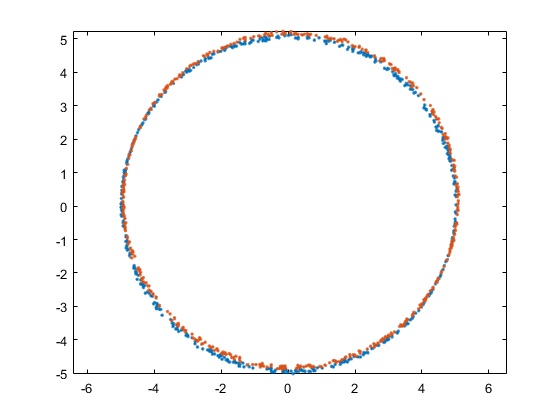

% We want to be able to overlay all molecules to their undrifted position
% to do this we will take various substacks of molecules and determine how
% to best overlay them ontop of each other.
% To determine best we define a cost function based on nearest neighbor
% distances of molecules between subsets
mol_chunks = 500; % every mol_chunks consecutive molecules will be used to do the comparison calculation
sub_locs_1 = sort_locs(1:mol_chunks,:);
sub_locs_2 = sort_locs(1*mol_chunks+1:2*mol_chunks,:);
plot(sub_locs_1(:,1),sub_locs_1(:,2),'.')
hold on
plot(sub_locs_2(:,1),sub_locs_2(:,2),'.')
hold off
axis equal

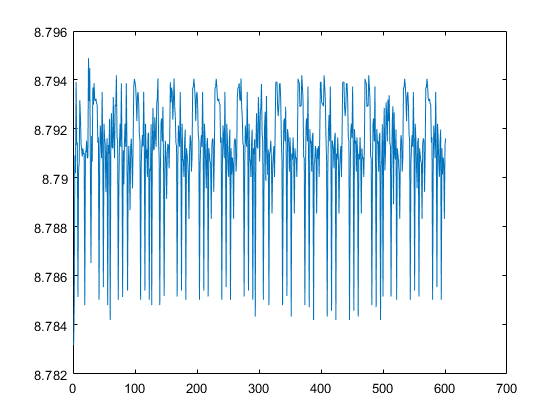

% Given a useful cost metric, we can now start iteratively trying to
% improve the overlay
last_cost = -1; % costs are positive definite (distances > 0)*(probability >0) > 0 initializing cost to negative ensures no accidental matching in the first loop
% best_x_move = -(mean(sub_locs_1(:,1)) - mean(sub_locs_2(:,1))); % 5 nm step size
% best_y_move = -(mean(sub_locs_1(:,2)) - mean(sub_locs_2(:,2)));
dx = 0.005;
dy = 0.005;
all_cost = [];
drift_x = 0;
dirft_y = 0;
gamma = 0.01;
while true % run untl we break
    % As the cost function appears convex, gradient descent seems like our
    % best bet, but in order to do that we'll need to establish a gradient
    % We'll treat sub_locs_1 as the initial group
    
    %Determine the partials in x
    sub_locs_2_px = sub_locs_2; % px indicated differential addition
    sub_locs_2_mx = sub_locs_2; % mx indicates differential subtraction
    sub_locs_2_px(:,1) = sub_locs_2(:,1) + dx;
    sub_locs_2_mx(:,1) = sub_locs_2(:,1) - dx;
    % Determine double partials that will be needed
    sub_locs_2_2px = sub_locs_2_px; % px indicated differential addition
    sub_locs_2_2mx = sub_locs_2_mx; % mx indicates differential subtraction
    sub_locs_2_2px(:,1) = sub_locs_2_px(:,1) + dx;
    sub_locs_2_2mx(:,1) = sub_locs_2_mx(:,1) - dx;
    
    cost = nn_drift_cost(sub_locs_1,sub_locs_2); % f(x)
    cost_px = nn_drift_cost(sub_locs_1,sub_locs_2_px); % f(x + dx)
    cost_mx = nn_drift_cost(sub_locs_1,sub_locs_2_mx); % f(x - dx)
    cost_2_px = nn_drift_cost(sub_locs_1,sub_locs_2_2px); % f(x + 2*dx)
    cost_2_mx = nn_drift_cost(sub_locs_1,sub_locs_2_2mx); % f(x - 2*dx)
    
    cost_x_prime = (cost_px - cost_mx)/dx; % Partial Derivative in x
    cost_x_2prime = (cost_2_px + cost_2_mx - 2*cost)/(dx)^2;
    best_x_move = -cost_x_prime*gamma;
    drift_x = best_x_move + drift_x;
    %Determine the partials in x
    sub_locs_2_px = sub_locs_2; % px indicated differential addition
    sub_locs_2_mx = sub_locs_2; % mx indicates differential subtraction
    sub_locs_2_px(:,2) = sub_locs_2(:,2) + dy;
    sub_locs_2_mx(:,2) = sub_locs_2(:,2) - dy;
    % Determine double partials that will be needed
    sub_locs_2_2px = sub_locs_2_px; % px indicated differential addition
    sub_locs_2_2mx = sub_locs_2_mx; % mx indicates differential subtraction
    sub_locs_2_2px(:,2) = sub_locs_2_px(:,2) + dy;
    sub_locs_2_2mx(:,2) = sub_locs_2_mx(:,2) - dy;
    
    cost = nn_drift_cost(sub_locs_1,sub_locs_2);
    cost_px = nn_drift_cost(sub_locs_1,sub_locs_2_px);
    cost_mx = nn_drift_cost(sub_locs_1,sub_locs_2_mx);
    cost_2_px = nn_drift_cost(sub_locs_1,sub_locs_2_2px);
    cost_2_mx = nn_drift_cost(sub_locs_1,sub_locs_2_2mx);
    
    cost_x_prime = (cost_px - cost_mx)/dy; % Partial Derivative in x
    cost_x_2prime = (cost_2_px + cost_2_mx - 2*cost)/(dy)^2;
    best_y_move = -cost_x_prime*gamma;
    drift_y = best_y_move + drift_y;
    if ~isnan(best_x_move) && ~isnan(best_y_move) && abs(best_y_move + best_x_move) < Inf
        sub_locs_2(:,1) = sub_locs_2(:,1) + best_x_move;
        sub_locs_2(:,2) = sub_locs_2(:,2) + best_y_move;
%         dx = best_x_move;
%         dy = best_y_move;
    else
        break
    end
    
%     if last_cost < nn_drift_cost(sub_locs_1,sub_locs_2) && last_cost ~= -1
%         sub_locs_2(:,1) = sub_locs_2(:,1) - best_x_move;
%         sub_locs_2(:,2) = sub_locs_2(:,2) - best_y_move;
%         break
%     else
%         last_cost = nn_drift_cost(sub_locs_1,sub_locs_2);
%     end
plot(sub_locs_1(:,1),sub_locs_1(:,2),'.')
hold on
plot(sub_locs_2(:,1),sub_locs_2(:,2),'.')
hold off
axis equal
plot(all_cost)
drawnow
all_cost = [all_cost;cost];

end